# APROKSYMACJA

## WYBÓR OPTYMALNEJ APROKSYMACJI - MIARY POPRAWNOŚCI MODELU

Jako użytkownicy metod aproksymacyjnych musimy umieć wybrać najbardziej odpowiedni model. W przypadku aproksymacji wielomianowej ograniczeni jesteśmy do modeli wielomianowych. Niemniej dla bardziej skomplikowanych modeli (ogólnego zagadnienia regresji) musimy mieć możliwości ocenienia czy nasze przypuszczenie, ze podstawową zależnością między faktycznymi danymi pomiarowymi, a naszym założeniem mówiącym o tym wg jakiej zależności te dane się zachowują jest słuszne. W tym celu wprowadzmy miary statystyczne. Przyjrzyjmy się jak działają takie miary.

Poniższy kod generuje kilka zestawów danych oraz uruchamia wbudowane w MATLABA narzędzie służące do optymalizacji modelu

% wytwórzmy przykładowe punkty do obliczenia aproksymacji
N = 20;                % 20 węzłów
a = 1;
b = 20;
fun1 = @(x) x.^6./exp(x);
fun2 = @(x) sin(x).*exp(-x);
fun3 = @(x) abs(x);
fun4 = @(x) polyval([ 3 2 1 0 1 7 5 2], x);



xx=linspace(a, b, N); 
y    = fun1(xx) * (1 + 2*(rand(1,numel(xx))-0.5).*0.10);   
yy   = fun2(xx);
yyy  = fun3(xx);
yyyy = fun4(xx);
%cftool;

Uruchom poniższy kod a następnie postępuj wg poniższych instrukcje:

1. Wybierz dane (węzły) do przeprowadzenia aproksymacji

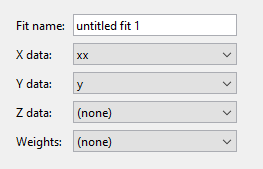

2. Wybierz dopasowanie za pomocą wielomianów i ustaw wybrany stopień wielomianu

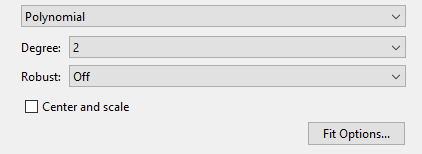

3. Włącz wyświetlanie residuów

4. Po zakończeniu obliczeń widoczny jest efekt aproksymacji, obliczone współczynniki oraz miary błędu

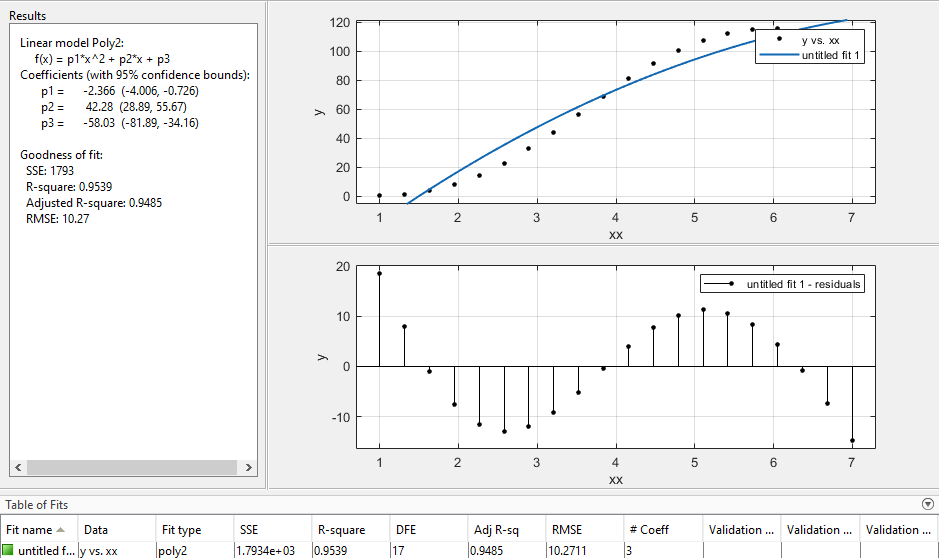

**ĆWICZENIE 1**

Dla wybranej funkcji zaobserwuj jak zmieniają się statystyczne miary błędu wraz z jakością odwzorowania (modelu). Zapisz jak wyglądają znane miary błędu dla badanej funkcji. Następnie zmień granice przedziału aproksymacji i powtórz te eksperymenty. Zastanów się jak rozumiesz różnice w miarach błędu i skąd się biorą?